## cleaning the data

ChinaDataUnclean1.total = ChinaDataUnclean1.Coal + ChinaDataUnclean1.Oil + ChinaDataUnclean1.Gas + ChinaDataUnclean1.Cement + ChinaDataUnclean1.Flaring + ChinaDataUnclean1.Other

ChinaDataUnclean1 = 117×13 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total      Coal     Oil    Gas    Cement    Flaring    Other    PerCapita    total 
    _______    ________________    _____    ____    ______    ______    ___    ___    ______    _______    _____    _________    ______

     China           CHN            156     1907    19.894    19.894     0      0       0          0         0      0.048403     19.894
     China           CHN            156     1908    22.736    22.736     0      0       0          0         0      


chn = ChinaDataUnclean1

chn = 117×13 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total      Coal     Oil    Gas    Cement    Flaring    Other    PerCapita    total 
    _______    ________________    _____    ____    ______    ______    ___    ___    ______    _______    _____    _________    ______

     China           CHN            156     1907    19.894    19.894     0      0       0          0         0      0.048403     19.894
     China           CHN            156     1908    22.736    22.736     0      0       0          0         0      0.055021     2


n = height(chn)

n = 117

train_size = floor(0.96 * n);

trainIdx = false(n, 1);
testIdx = false(n, 1);

trainIdx(1:train_size) = true;
testIdx(train_size + 1:end) = true;

chnTrain = chn(trainIdx, :);
chnTest = chn(testIdx, :);

disp(['Training set size: ', num2str(sum(trainIdx))]);

Training set size: 112


disp(['Test set size: ', num2str(sum(testIdx))]);

Test set size: 5


## visualize current

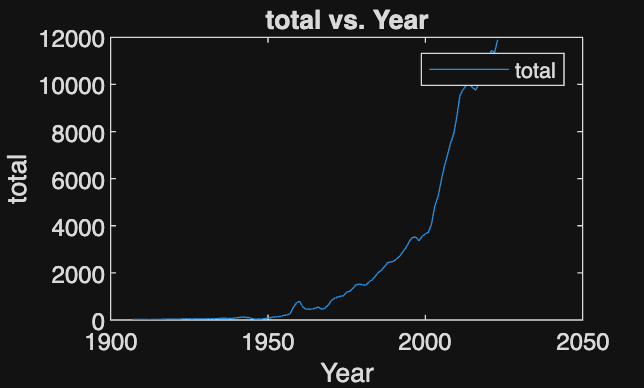

% Create plot of ChinaDataUnclean1.Year and ChinaDataUnclean1.total
h = plot(ChinaDataUnclean1,"Year","total","DisplayName","total");

% Add xlabel, ylabel, title, and legend
xlabel("Year")
ylabel("total")
title("total vs. Year")
legend

## make data stationary

% taking the log
chnTrain.log = log(chnTrain.Total);

% make data stationary

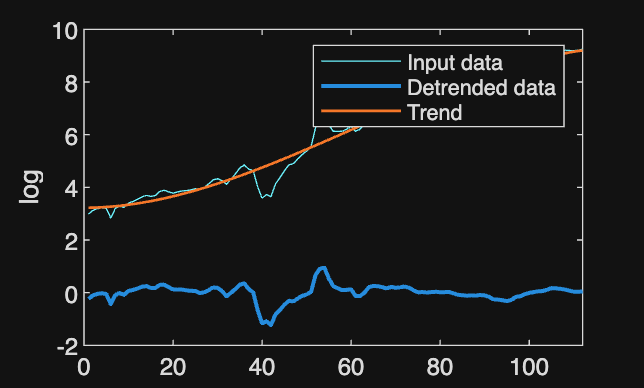

% Remove trend from input data
cubicTrend = detrend(chnTrain,3,DataVariables="log");

% Display results
figure
plot(chnTrain.log,SeriesIndex=6,DisplayName="Input data")
hold on
plot(cubicTrend.log,SeriesIndex=1,LineWidth=1.5,DisplayName="Detrended data")
plot(chnTrain.log-cubicTrend.log,SeriesIndex=2,LineWidth=1,DisplayName="Trend")
hold off
legend
ylabel("log")

% Remove trend from input data
cubicTrend = detrend(chnTrain, 3, DataVariables = "log");

% Save detrended data
chnTrain.cubeDetrended = cubicTrend.log

chnTrain = 112×15 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total      Coal     Oil    Gas    Cement    Flaring    Other    PerCapita    total      log      cubeDetrended
    _______    ________________    _____    ____    ______    ______    ___    ___    ______    _______    _____    _________    ______    ______    _____________

     China           CHN            156     1907    19.894    19.894     0      0       0          0         0      0.048403     19.894    


% Save cubic trend to model
chnTrain.cubicTrend = chnTrain.log - cubicTrend.log

chnTrain = 112×16 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total      Coal     Oil    Gas    Cement    Flaring    Other    PerCapita    total      log      cubeDetrended    cubicTrend
    _______    ________________    _____    ____    ______    ______    ___    ___    ______    _______    _____    _________    ______    ______    _____________    __________

     China           CHN            156     1907    19.894    19.894     0   


% Extracted cubic trend plot

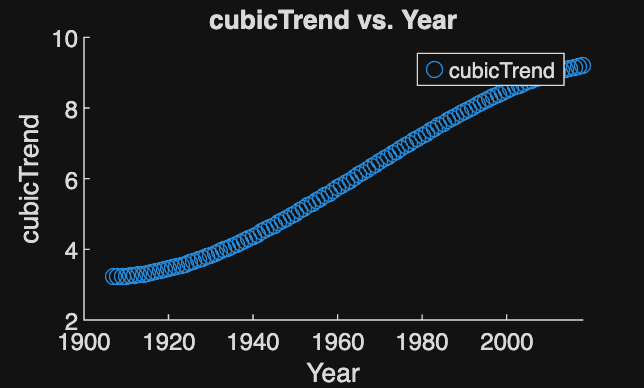

% Create scatter of chnTrain.Year and chnTrain.cubicTrend
cubicTrend = scatter(chnTrain,"Year","cubicTrend","DisplayName","cubicTrend");

% Add xlabel, ylabel, title, and legend
xlabel("Year")
ylabel("cubicTrend")
title("cubicTrend vs. Year")
legend


% Cubic DETRENDED data

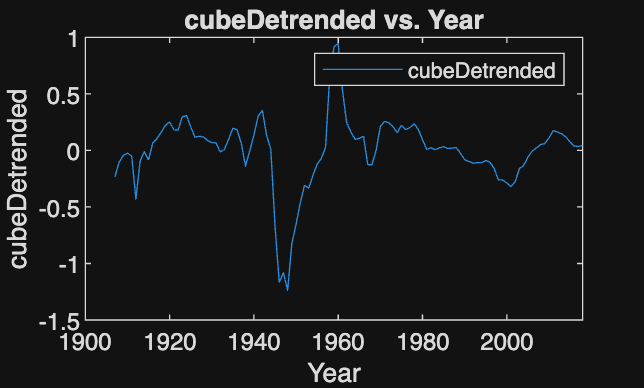

% Create plot of chnTrain.Year and chnTrain.cubeDetrended
cubicDetrended = plot(chnTrain,"Year","cubeDetrended","DisplayName","cubeDetrended");

% Add xlabel, ylabel, title, and legend
xlabel("Year")
ylabel("cubeDetrended")
title("cubeDetrended vs. Year")
legend

## Decomposition

just to look at the long-term, seasonality, and remainder components

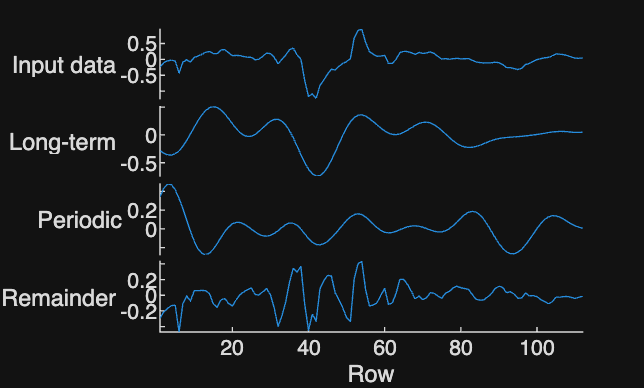

% Decompose data into long-term trend, seasonal trends, and remainder
trends = trenddecomp(chnTrain(:,"cubeDetrended"),"ssa",56,NumSeasonal=1);

% Display results
figure
stackedplot([chnTrain(:,15) trends],"DisplayLabels",["Input data","Long-term", ...
    "Periodic","Remainder"]);

% I skipped creating models for them --> I can go back

## ACF & PCF graphs

% I used the econometric app

## ARIMA model

function ARIMA_cubeDetrended = modelTimeSeries(chnTrain)
%%Time Series Modeling Using the Econometric Modeler
% This code recreates the estimated model produced in the Econometric Modeler app. Use the code below to estimate the same model, or estimate a model with the same parameters on a new set of data.
%
%Input: A table with the same variables as the table imported into the app (chnTrain)
%
%Output: The model containing estimated parameters (ARIMA_cubeDetrended)
%
%Auto-generated by MATLAB (R2025a) and Econometrics Toolbox Version 25.1 on 10-Nov-2025 19:55:08
cubeDetrended = chnTrain.cubeDetrended;

%% Autoregressive Integrated Moving Average Model
%Estimate an ARIMA Model of cubeDetrended
ARIMA_cubeDetrended = arima('Constant',NaN,'ARLags',1,'D',1,'MALags',1,'Distribution','Gaussian');
ARIMA_cubeDetrended = estimate(ARIMA_cubeDetrended,cubeDetrended,'Display','off');
end

## Model Cubic

function [fitresult, gof] = createFit(Year, cubicTrend)
%CREATEFIT(YEAR,CUBICTREND)
%  Create a fit.
%
%  Data for 'CubicMdl' fit:
%      X Input: Year from chnTrain
%      Y Output: cubicTrend from chnTrain
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 10-Nov-2025 20:15:42


%% Fit: 'CubicMdl'.
[xData, yData] = prepareCurveData( Year, cubicTrend );

% Set up fittype and options.
ft = fittype( 'poly3' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'CubicMdl' );
h = plot( fitresult, xData, yData );
legend( h, 'cubicTrend vs. Year', 'CubicMdl', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Year', 'Interpreter', 'none' );
ylabel( 'cubicTrend', 'Interpreter', 'none' );
grid on
end


## Model Selection + Forecasting

frcst = table;
frcst.Year = chnTest.Year;
prevIdx = height(chnTrain)

prevIdx = 112


frcst.Idx = (prevIdx + 1:prevIdx + height(frcst))'

frcst = 5×2 table
    Year    Idx
    ____    ___

    2019    113
    2020    114
    2021    115
    2022    116
    2023    117



frcstHorizon = height(frcst)

frcstHorizon = 5


frcst.CubicFrcst = feval(CubicMdl, frcst.Idx);

## Forecasting for next 5 years

putting a pin in the arima parameter search --> will use (2, 0, 1) respectively

bestModel = arima(2, 0, 1);
bestARIMAfit = estimate(bestModel, chnTrain.cubeDetrended, 'Display', 'off');

frcst.ARIMABest = forecast(bestARIMAfit, frcstHorizon, chnTrain.cubeDetrended);
disp(bestARIMAfit);

  arima with properties:

     Description: "ARIMA(2,0,1) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 2
               D: 0
               Q: 1
        Constant: 0.000662056
              AR: {1.41858 -0.566638} at lags [1 2]
             SAR: {}
              MA: {-0.195563} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.0174546



% Untransform
frcst.Co2Forecast = exp(frcst.ARIMABest + frcst.CubicFrcst);

## Calculating RMSE

% Calculate RMSE
%remove 2019 2020
E = rmse(frcst.Co2Forecast(3:5, :), chnTest.Total(3:5, :));

% Display the result
disp(['The RMSE is: ', num2str(E)]);

The RMSE is: Inf


## Plot

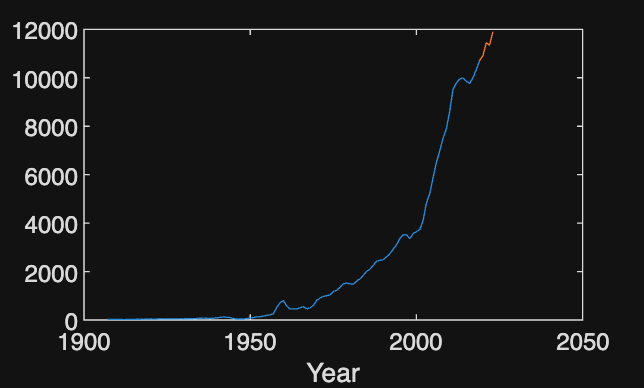

figure
plot(chn, "Year", "Total")
hold on
plot(chnTest, "Year", "Total")
hold on
plot(frcst,"Year","Co2Forecast")
hold off